jam1 = 1.0e+02 *

  -0.0010 + 0.0038i  -0.0027 - 0.0041i   0.0030 - 0.0088i   0.0111 - 0.0044i   0.0054 + 0.0070i  -0.0044 + 0.0205i  -0.0212 + 0.0313i  -0.0274 + 0.0086i  -0.0106 - 0.0413i   0.0398 - 0.0888i   0.0811 - 0.0940i   0.0765 - 0.0107i   0.0006 + 0.1449i  -0.1331 + 0.2862i  -0.2603 + 0.3056i  -0.2874 + 0.1323i  -0.1887 - 0.1809i  -0.0355 - 0.4818i   0.0189 - 0.5558i  -0.1806 - 0.2925i  -0.6835 + 0.2692i  -1.3752 + 0.9096i  -2.0060 + 1.3418i  -2.3011 + 1.3499i  -2.1011 + 0.9087i  -1.4625 + 0.1847i  -0.6210 - 0.5430i   0.0969 - 1.0310i   0.4322 - 1.1344i   0.3200 - 0.8807i  -0.1374 - 0.4038i  -0.7044 + 0.1237i  -1.1533 + 0.5584i  -1.3331 + 0.8267i  -1.2289 + 0.9010i  -0.8971 + 0.7923i  -0.4416 + 0.5376i   0.0179 + 0.1408i   0.3874 - 0.3650i   0.5954 - 0.9171i   0.5742 - 1.3838i   0.3336 - 1.6133i  -0.0875 - 1.4664i  -0.5519 - 0.9371i  -0.9188 - 0.1709i  -1.0497 + 0.5819i  -0.9337 + 1.0720i  -0.6687 + 1.2031i  -0.4114 + 1.0749i  -0.2922 + 0.9070i


jam2 = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


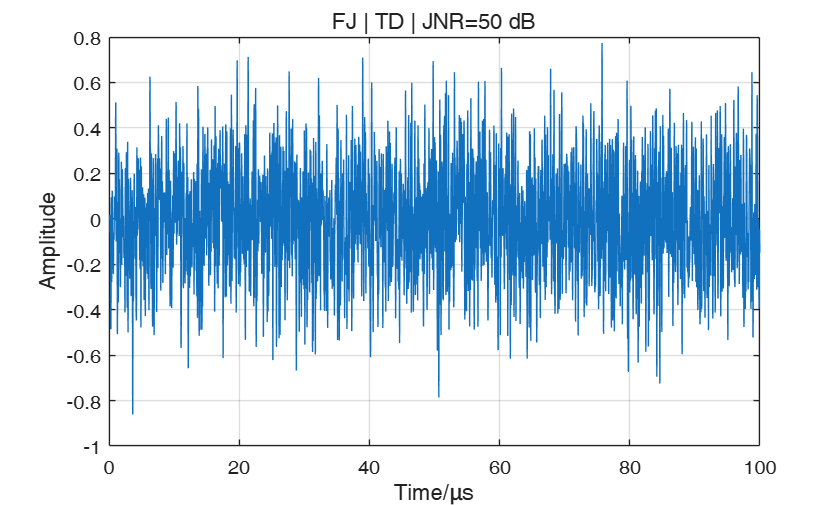

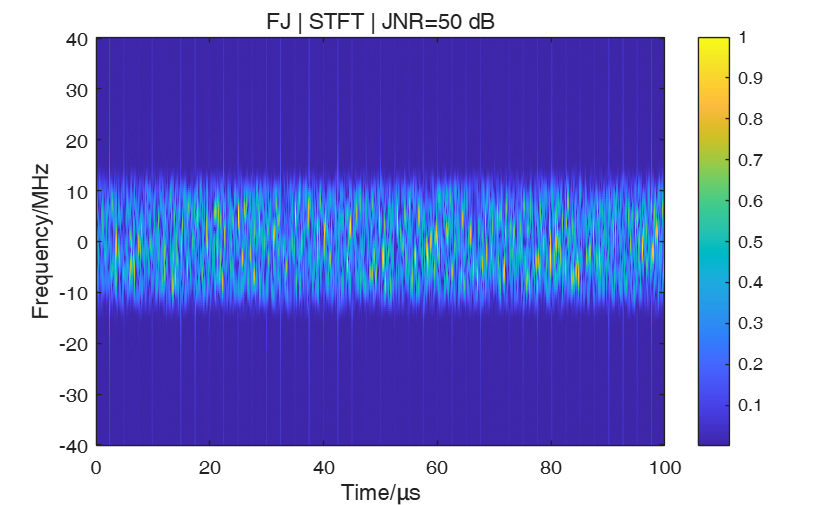

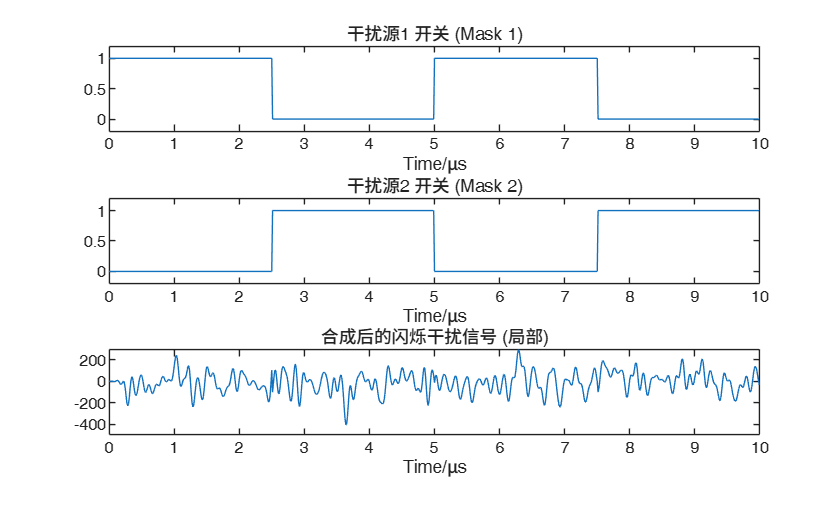

% 2025.09.12
% 产生闪烁干扰作为分类数据，20-40Mhz带宽
close all;clear;clc
j=sqrt(-1);
data_num=1;     %干扰样本数
num_label = 13;  %信号标签
samp_num=8000;  %距离窗点数

fs = 80e6;          % 采样频率 80MHz
ts = 1/fs;          % 采样时间间隔
T = samp_num * ts;  % 信号总时宽 (与您的原定义保持一致)
N = samp_num;       % 采样点数
t = (0:N-1)*ts;     % 总时间窗口

%% 1.定义线性调频信号 (LFM) - (这部分保持不变)
taup = 20e-6;       % 信号脉宽 20μs
Ntau = round(taup*fs);    % 采样点数
ttau = (-Ntau/2:1:Ntau/2-1)*ts;     % LFM时间窗口
B  = 10e6;          % 信号带宽 10MHz
lfm = exp(1j*pi*B/taup*ttau.^2);          %LFM信号 (基带)

% -------------------------------------------------------------------------
% --- 新增：定义闪烁干扰参数 ---
% -------------------------------------------------------------------------
f_flicker = 20e4; % 闪烁频率，例如 20 kHz。这是两个干扰源切换的频率。
                  % 这个频率通常需要根据雷达跟踪环路的带宽来设计。
                  % 这里我们先设定一个值用于仿真。
% -------------------------------------------------------------------------


%% 2. 循环生成数据
% (原代码大部分逻辑移入循环中)

echo=zeros(data_num,samp_num,4);     
echo_stft=zeros(data_num,101,249,4);  % 调整了一下维度以匹配spectrogram输出

label=zeros(1,data_num)+num_label;                         %标签数据

for m=1:data_num
    
    % --- 定义目标和干扰参数 ---
    SNR=15; %信噪比dB
    JNR=50; %干噪比50dB
    
    As=10^(SNR/20); %目标回波幅度
    Aj=10^(JNR/20); %干扰回波幅度

    % --- 生成背景白噪声 ---
    background_noise = randn([1,samp_num]) + 1j*randn([1,samp_num]);
    background_noise = background_noise / std(background_noise); % 归一化功率
    
    % --- 嵌入目标信号 ---
    range_tar = 1 + round(rand(1,1)*4000); % 目标随机位置
    signal = background_noise;
    signal(1+range_tar : length(lfm)+range_tar) = signal(1+range_tar : length(lfm)+range_tar) + As*lfm;  
    pure_echo = 0*background_noise;
    pure_echo(1+range_tar:length(lfm)+range_tar) = pure_echo(1+range_tar:length(lfm)+range_tar)+As*lfm;

    
    % ---------------------------------------------------------------------
    % --- 核心修改：生成闪烁干扰 ---
    % ---------------------------------------------------------------------
    
    % 1. 创建两个独立的带限噪声源 (Jammer 1 和 Jammer 2)
    Bj = 20e6;  % 干扰带宽固定20MHz
    fjc = 0e6;  % 干扰中心频率 (这里为了简化，设在基带)

    % 创建带通滤波器
    lpFilt = fir1(34, Bj/(fs)); 
    
    % Jammer 1
    noise_base1 = randn([1,samp_num]) + 1j*randn([1,samp_num]);
    noise_base1 = noise_base1 / std(noise_base1);
    jammer1 = filter(lpFilt, 1, noise_base1);
    jammer1 = jammer1 .* exp(1j*2*pi*fjc*t);

    % Jammer 2 (必须是独立的噪声源)
    noise_base2 = randn([1,samp_num]) + 1j*randn([1,samp_num]);
    noise_base2 = noise_base2 / std(noise_base2);
    jammer2 = filter(lpFilt, 1, noise_base2);
    jammer2 = jammer2 .* exp(1j*2*pi*fjc*t);

    % 2. 创建交替开关的"掩模"(Mask)
    % 使用square函数生成一个在-1和+1之间切换的方波
    flicker_wave = square(2 * pi * f_flicker * t, 50); % 50%占空比
    
    % 将方波转换成0和1的开关掩模
    mask1 = (flicker_wave + 1) / 2; % 当方波为+1时, mask1为1; 当方波为-1时, mask1为0
    mask2 = 1 - mask1;              % mask2与mask1完全相反
    
    % 3. 将掩模应用到两个干扰源上，并合成总的闪烁干扰
    total_flicker_jammer = Aj * (jammer1 .* mask1 + jammer2 .* mask2);
    jam1 = Aj *jammer1 .* mask1
    jam2 = Aj *jammer2 .* mask2
    
    % --- 将闪烁干扰叠加到信号上 ---
    final_signal = signal + total_flicker_jammer; 
    
    % 归一化处理
    final_signal = final_signal / max(abs(final_signal));
    
    % --- 存储和显示结果 ---
    sp_abs = abs(final_signal);
    
    % 存储数据
    echo(m,:,1) = real(final_signal); 
    echo(m,:,2) = imag(final_signal);
    echo(m,:,3) = sp_abs;
    echo(m,:,4) = angle(final_signal); 
    
    % --- 时域图 ---
    figure(1);
    plot(t*1e6, real(final_signal));
    title(sprintf('FJ | TD | JNR=%d dB', JNR));
    xlabel('Time/μs'); ylabel('Amplitude');
    grid on;
    
    % --- 时频图 (Spectrogram) ---
    % [S,F_s,T_s] = spectrogram(final_signal, 128, 120, 256, fs, 'centered');
    % S_abs = abs(S);
    % 
    % figure(2);
    % imagesc(T_s*1e6, F_s/1e6, S_abs);
    [S,F,T] = spectrogram(final_signal,32,32-8,200,fs,'centered');
    
    S=S/max(max(S));
    S_abs=abs(S);
     figure(2)
    imagesc(linspace(0,100,size(S,1)), linspace(-40,40,size(S,2)),abs(S));
    axis xy; % 让Y轴方向正确
    title(sprintf('FJ | STFT | JNR=%d dB', JNR)); 
    ylabel('Frequency/MHz'); xlabel('Time/μs');
    colorbar;

    % 存储STFT结果 (注意维度匹配)
    % echo_stft(m,1:size(S,1),1:size(S,2),1)=real(S);
    % ... (如果需要，可以取消这部分注释)
    
    % --- 可选：可视化开关过程 ---
    if m == 1 % 只画第一个样本的开关图
        figure(5);
        subplot(3,1,1);
        plot(t(1:800)*1e6, mask1(1:800)); title('干扰源1 开关 (Mask 1)'); ylim([-0.2 1.2]);
        xlabel('Time/μs');
        subplot(3,1,2);
        plot(t(1:800)*1e6, mask2(1:800)); title('干扰源2 开关 (Mask 2)'); ylim([-0.2 1.2]);
        xlabel('Time/μs');
        subplot(3,1,3);
        plot(t(1:800)*1e6, real(total_flicker_jammer(1:800))); title('合成后的闪烁干扰信号 (局部)');
        xlabel('Time/μs');
    end

end

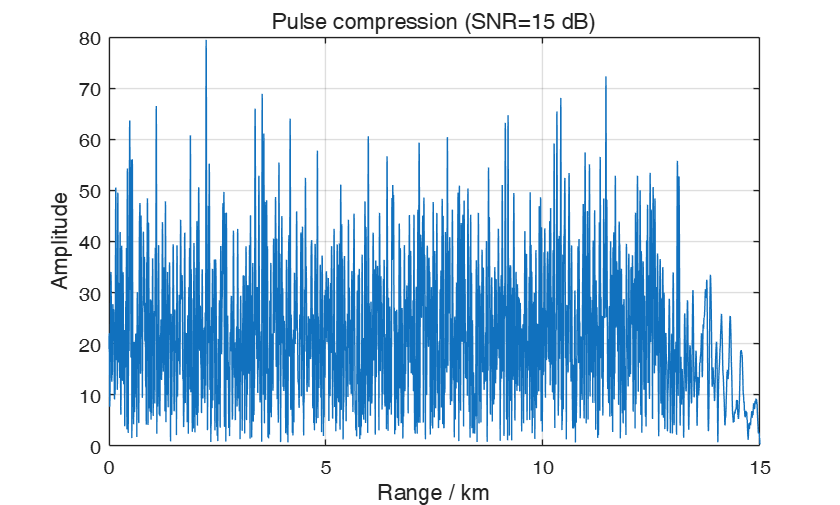


% --- 脉冲压缩 (使用最后一个样本进行演示) ---
s_ref = lfm;                    
h = conj(flip(s_ref));
y = conv(final_signal, h);
Np = length(s_ref);
y_aligned = y(Np:end);          
env = abs(y_aligned);

% 距离轴
c = 3e8;
rng_axis = (0:length(env)-1) * ts * c/2;

% 绘图
figure(6);
plot(rng_axis/1000, env);
xlabel('Range / km'); ylabel('Amplitude');
title(sprintf('Pulse compression (SNR=%d dB)', SNR));
grid on;